Read audio files

[signal1, Fs_signal1] = audioread("1.wav");
signal1 = signal1(:,1) + signal1(:,2);
lenSignal1 = length(signal1)

lenSignal1 = 236160

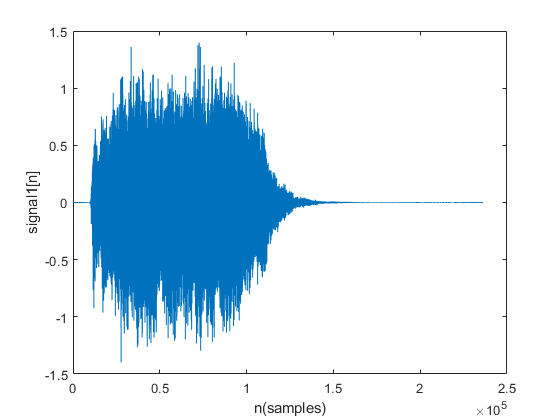

plot(signal1)
xlabel("n(samples)")
ylabel("signal1[n]")


[signal2, Fs_signal2] = audioread("2.wav");
signal2 = signal2(:,1) + signal2(:,2);
lenSignal2 = length(signal2)

lenSignal2 = 298368

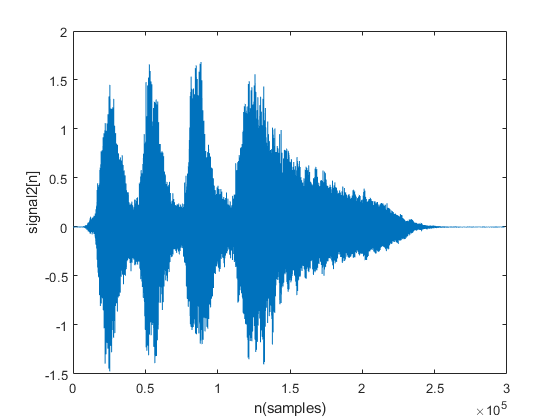

plot(signal2)
xlabel("n(samples)")
ylabel("signal2[n]")


[signal3, Fs_signal3] = audioread("3.wav");
signal3 = signal3(:,1) + signal3(:,2);
lenSignal3 = length(signal3)

lenSignal3 = 277632

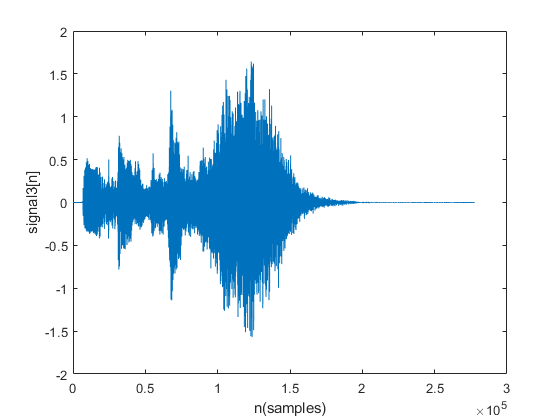

plot(signal3)
xlabel("n(samples)")
ylabel("signal3[n]")

Convert to Frequency domain

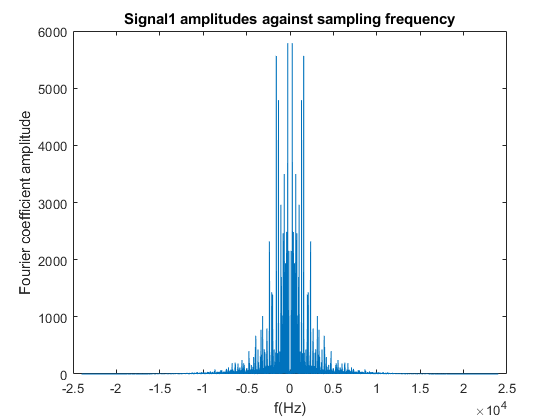

% Get the frequency increments
% f_signal1 = (Fs_signal1/lenSignal1)  * (0 : lenSignal1 - 1);
f_signal1=(-Fs_signal1/2:Fs_signal1/lenSignal1:Fs_signal1/2-Fs_signal1/lenSignal1);%frequency axis
fft_signal1 = abs(fft(signal1));
plot(f_signal1, fftshift(fft_signal1))
xlabel("f(Hz)")
ylabel("Fourier coefficient amplitude")
title("Signal1 amplitudes against sampling frequency")

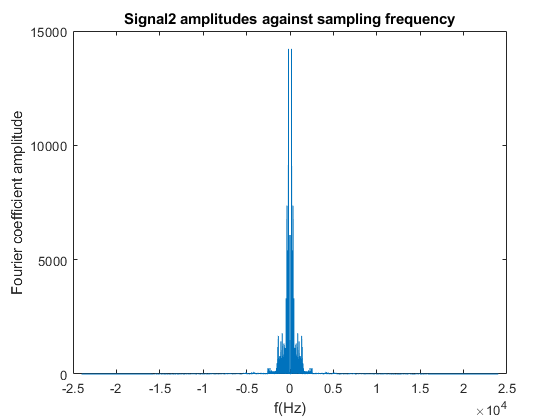


% f_signal2 = (Fs_signal2/lenSignal2)  * (0: lenSignal2 - 1);
f_signal2=(-Fs_signal2/2:Fs_signal2/lenSignal2:Fs_signal2/2-Fs_signal2/lenSignal2);%frequency axis
fft_signal2 = abs(fft(signal2));
plot(f_signal2, fftshift(fft_signal2))
xlabel("f(Hz)")
ylabel("Fourier coefficient amplitude")
title("Signal2 amplitudes against sampling frequency")

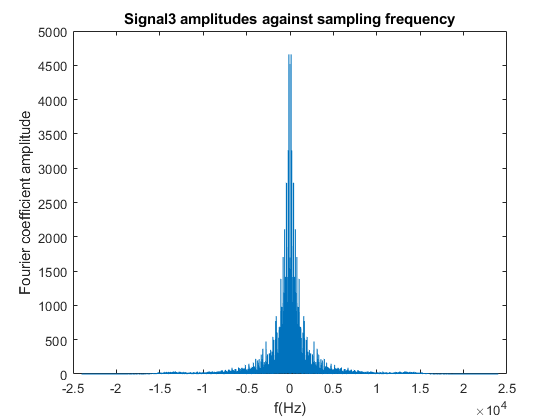


% f_signal3 = (Fs_signal3/lenSignal3)  * (0: lenSignal3 - 1);
f_signal3=(-Fs_signal3/2:Fs_signal3/lenSignal3:Fs_signal3/2-Fs_signal3/lenSignal3);%frequency axis
fft_signal3 = abs(fft(signal3));
plot(f_signal3, fftshift(fft_signal3))
xlabel("f(Hz)")
ylabel("Fourier coefficient amplitude")
title("Signal3 amplitudes against sampling frequency")

Resampling the signals

Fs_new = 250000;
[P, Q] = rat(Fs_new/Fs_signal1);
re_signal1 = resample(signal1, P, Q);

[P, Q] = rat(Fs_new/Fs_signal2);
re_signal2 = resample(signal2, P, Q);

[P, Q] = rat(Fs_new/Fs_signal3);
re_signal3 = resample(signal3, P, Q);

Modulation

Generate the carrier

freq1 = 50000; 
freq2 = 100000;

testTimeScale1 = (0:length(re_signal1) - 1) * (1/Fs_new);
carrier1 = cos(2*pi*(freq1) * testTimeScale1);

testTimeScale2 = (0:length(re_signal2) - 1) * (1/Fs_new);
carrier2 = cos(2*pi*(freq2) * testTimeScale2);

testTimeScale3 = (0:length(re_signal3) - 1) * (1/Fs_new);
carrier3 = sin(2*pi*(freq2) * testTimeScale3);

Modulating the  carriers

mod_signal1 = re_signal1 .* carrier1';
mod_signal2 = re_signal2 .* carrier2';
mod_signal3 = re_signal3 .* carrier3';

Plot Modulated signals

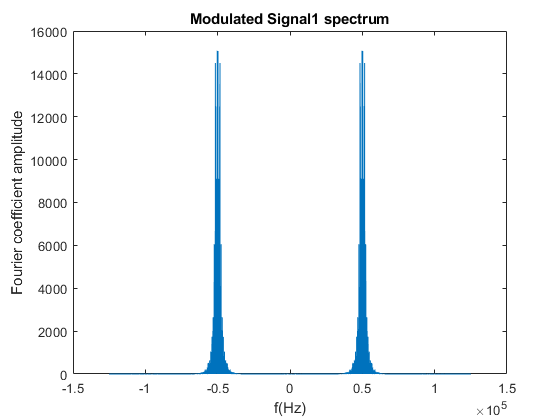

len_mod_signal1 = length(mod_signal1);
len_mod_signal2 = length(mod_signal2);
len_mod_signal3 = length(mod_signal3);
% Get the frequency increments
f_m_signal1 = (Fs_new/len_mod_signal1)  * (-len_mod_signal1/2: len_mod_signal1/2 - 1);
fft_m_signal1 = abs(fft(mod_signal1));
plot(f_m_signal1, fftshift(fft_m_signal1))
xlabel("f(Hz)")
ylabel("Fourier coefficient amplitude")
title("Modulated Signal1 spectrum")

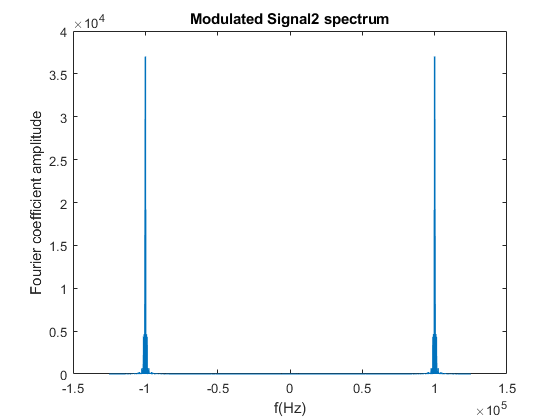


f_m_signal2 = (Fs_new/len_mod_signal2)  * (-len_mod_signal2/2: len_mod_signal2/2 - 1);
fft_m_signal2 = abs(fft(mod_signal2));
plot(f_m_signal2, fftshift(fft_m_signal2))
xlabel("f(Hz)")
ylabel("Fourier coefficient amplitude")
title("Modulated Signal2 spectrum")

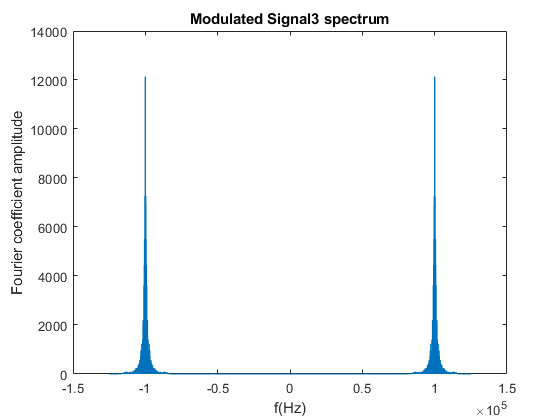


f_m_signal3 = (Fs_new/len_mod_signal3)  * (-len_mod_signal3/2: len_mod_signal3/2 - 1);
fft_m_signal3 = abs(fft(mod_signal3));
plot(f_m_signal3, fftshift(fft_m_signal3))
xlabel("f(Hz)")
ylabel("Fourier coefficient amplitude")
title("Modulated Signal3 spectrum")

Adding the modulated Signal

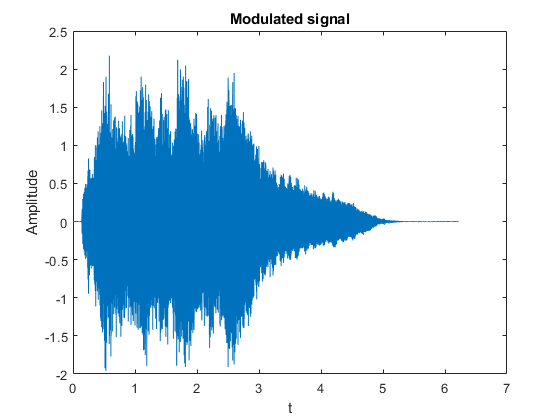

max_len = max(len_mod_signal1, max(len_mod_signal2, len_mod_signal3));
s1 = [mod_signal1;zeros(max_len-len_mod_signal1, 1)];
s2 = [mod_signal2;zeros(max_len-len_mod_signal2, 1)];
s3 = [mod_signal3;zeros(max_len-len_mod_signal3, 1)];

mod_s = s1 + s2 + s3;

t_ms = (0: max_len - 1) * (1 / Fs_new);
f_ms = (-max_len/2 : max_len/2 - 1) * (Fs_new / max_len);

plot(t_ms, mod_s);xlabel("t");ylabel("Amplitude")
title("Modulated signal")

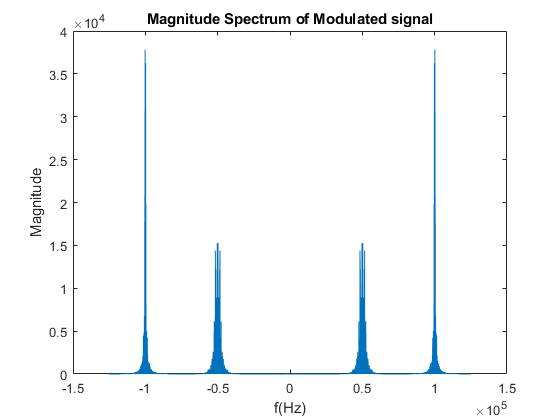


fft_mod_s = abs(fft(mod_s));
plot(f_ms, fftshift(fft_mod_s))
xlabel("f(Hz)");ylabel("Magnitude");title("Magnitude Spectrum of Modulated signal")

Demodulation synchronous carriers

tdem = (0:max_len - 1) * (1/Fs_new);
sync_carr1 = cos(2*pi*(freq1) * tdem);

sync_carr2 = cos(2*pi*(freq2) * tdem);

sync_carr3 = sin(2*pi*(freq2) * tdem);

Demodulation & Filtering

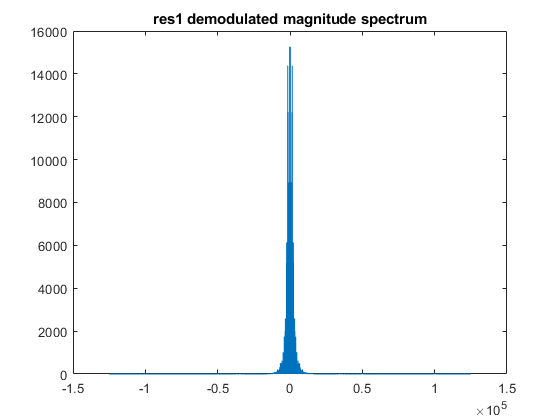

f_res = (-max_len/2 : max_len/2 - 1) * (Fs_new / max_len);

demodulate_signal(mod_s, sync_carr1, lenSignal1, Fs_signal1, Fs_new, 24000, f_res, 'res1')

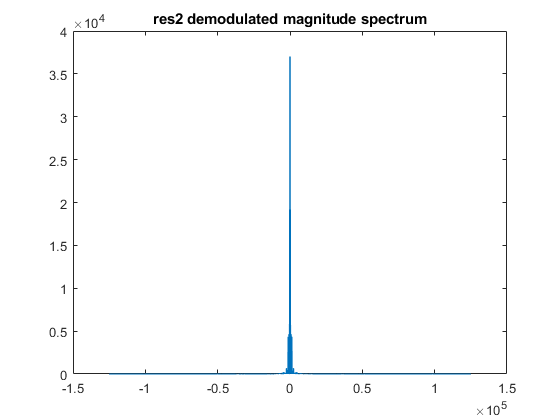

demodulate_signal(mod_s, sync_carr2, lenSignal2, Fs_signal2, Fs_new, 24000, f_res, 'res2')

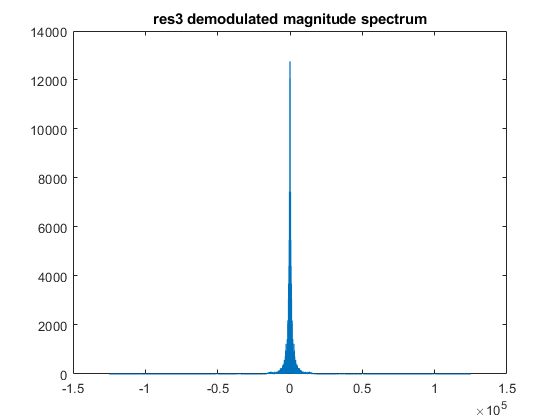

demodulate_signal(mod_s, sync_carr3, lenSignal3, Fs_signal3, Fs_new, 24000, f_res, 'res3')

Phase shift 10

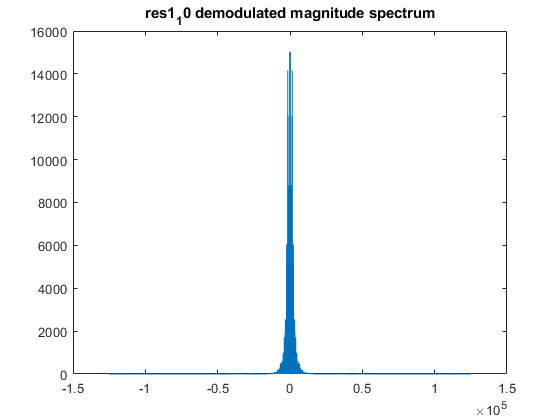

[carr1_10, carr2_10, carr3_10] = gen_carriers(freq1, freq2, tdem, 10);
demodulate_signal(mod_s, carr1_10, lenSignal1, Fs_signal1, Fs_new, 24000, f_res, 'res1_10')

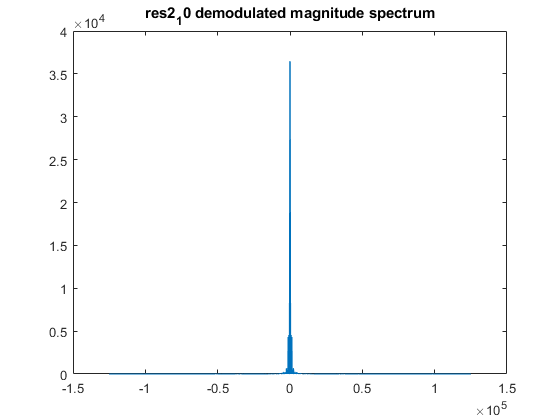

demodulate_signal(mod_s, carr2_10, lenSignal2, Fs_signal2, Fs_new, 24000, f_res, 'res2_10')

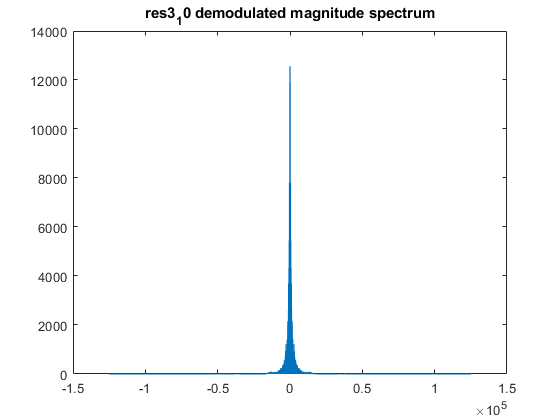

demodulate_signal(mod_s, carr3_10, lenSignal3, Fs_signal3, Fs_new, 24000, f_res, 'res3_10')

Phase shift 30

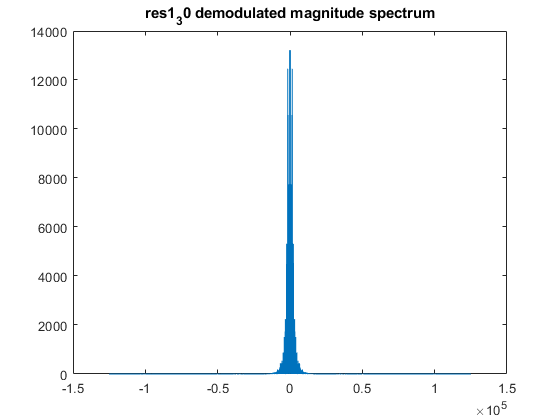

[carr1_30, carr2_30, carr3_30] = gen_carriers(freq1, freq2, tdem, 30);
demodulate_signal(mod_s, carr1_30, lenSignal1, Fs_signal1, Fs_new, 24000, f_res, 'res1_30')

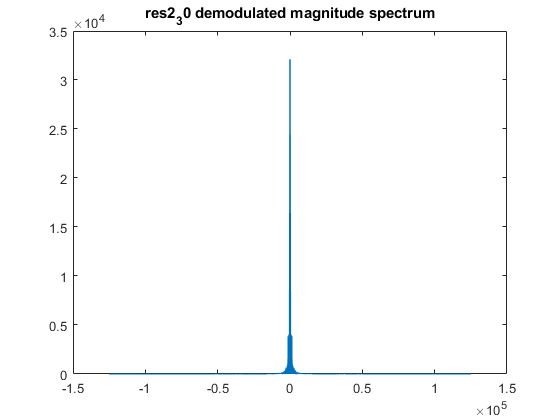

demodulate_signal(mod_s, carr2_30, lenSignal2, Fs_signal2, Fs_new, 24000, f_res, 'res2_30')

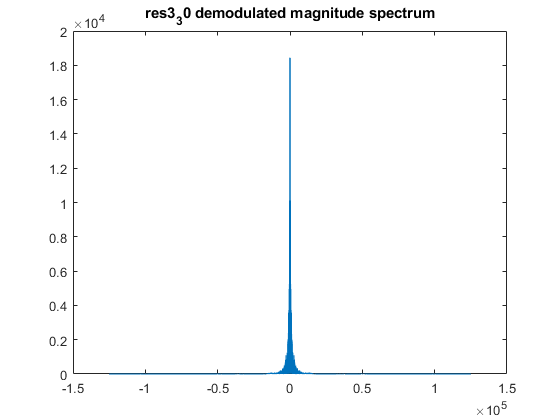

demodulate_signal(mod_s, carr3_30, lenSignal3, Fs_signal3, Fs_new, 24000, f_res, 'res3_30')

Phase shift 90

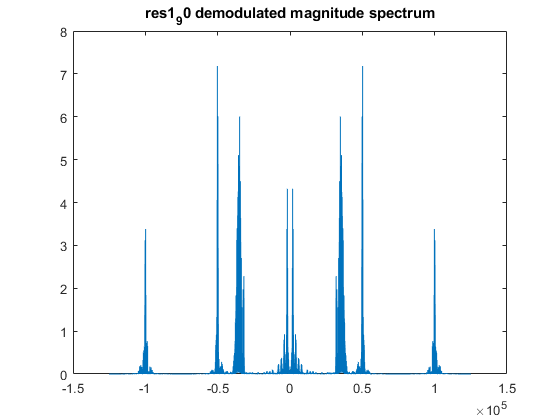

[carr1_90, carr2_90, carr3_90] = gen_carriers(freq1, freq2, tdem, 90);
demodulate_signal(mod_s, carr1_90, lenSignal1, Fs_signal1, Fs_new, 24000, f_res, 'res1_90')

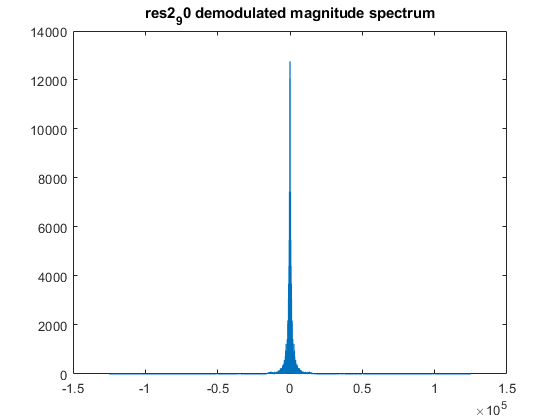

demodulate_signal(mod_s, carr2_90, lenSignal2, Fs_signal2, Fs_new, 24000, f_res, 'res2_90')

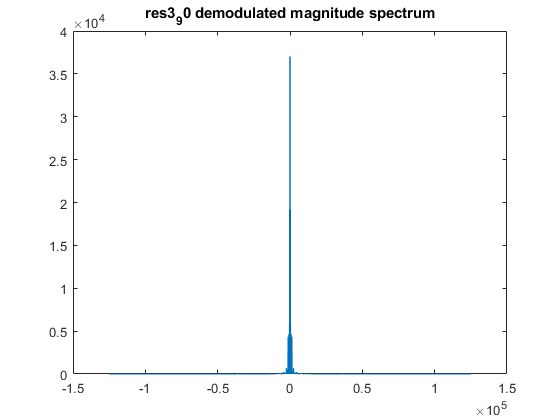

demodulate_signal(mod_s, carr3_90, lenSignal3, Fs_signal3, Fs_new, 24000, f_res, 'res3_90')

function  demodulate_signal(s, carr, old_len, fs_old, fs_new, f_pass, f_res, filename)
    res_s = s .* carr';
    res = lowpass(res_s, f_pass , fs_new);
    
    fft_res_s = abs(fft(res));
    plot(f_res, fftshift(fft_res_s))
    title(strcat(filename, " demodulated magnitude spectrum"))
    
    [P, Q] = rat(fs_old/fs_new);
    res = resample(res, P, Q);
    
    % clip to original size
    res = res(1: old_len);
    
    audiowrite(strcat(filename, '.wav'), res, fs_old)
end

function [c1, c2, c3] = gen_carriers(f1, f2, tdim, phase_shift_deg)
     phase_shift_rad = (phase_shift_deg * pi) / 180; 
     c1 = cos(2*pi*f1*tdim + phase_shift_rad);
     c2 = cos(2*pi*f2*tdim + phase_shift_rad);
     c3 = sin(2*pi*f2*tdim + phase_shift_rad);
end